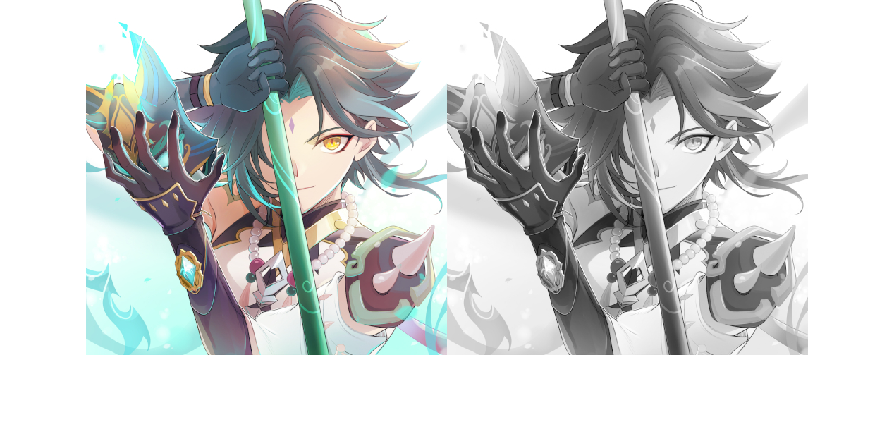

im = imread("yaksha.jpg");
img = rgb2gray(im);
imshowpair(im, img, "montage");

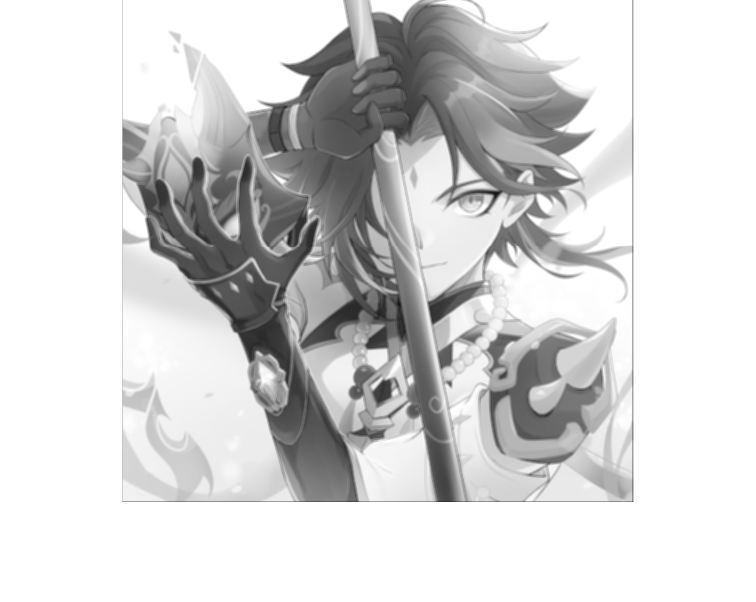

ima = filter2(fspecial("average",3),img) / 255;
imshow(ima)

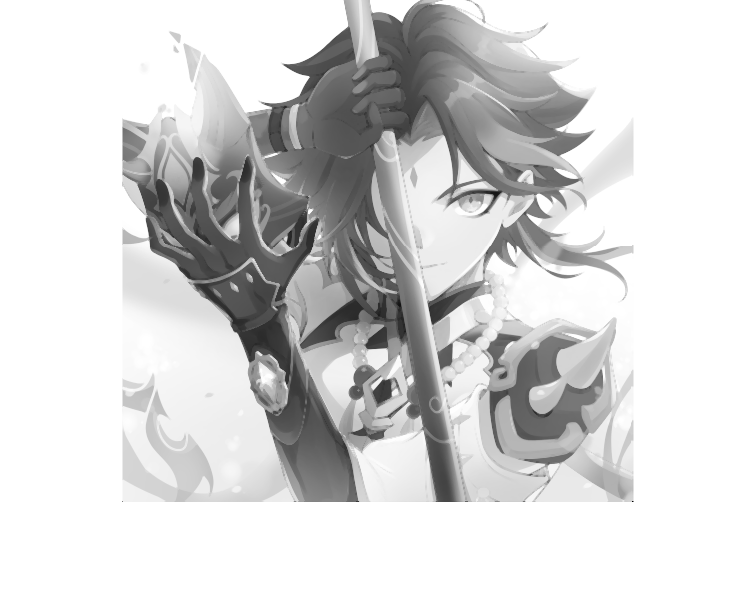

imwrite(ima, "exp5/ave_" + fn)
imm = medfilt2(img);
imshow(imm)

imwrite(imm, "exp5/med_" + fn)

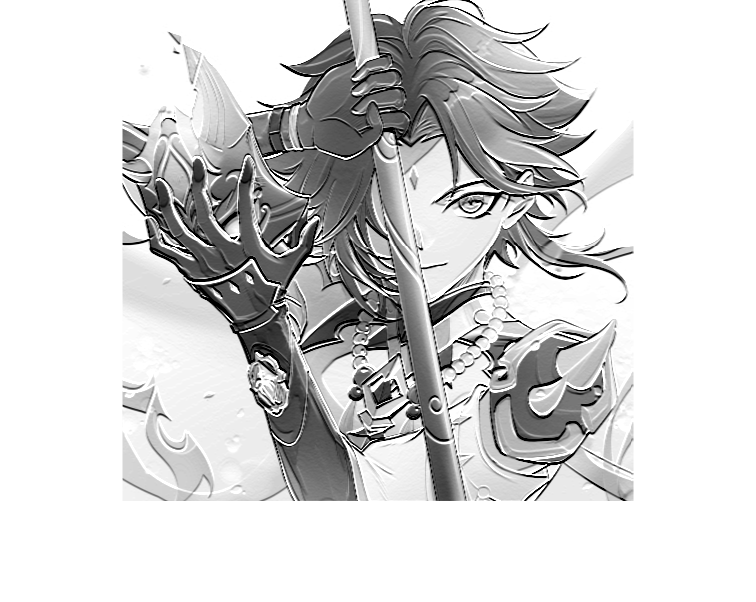

ims = filter2(fspecial("sobel"),img) / 255;
imshow(ims + double(img) / 255)

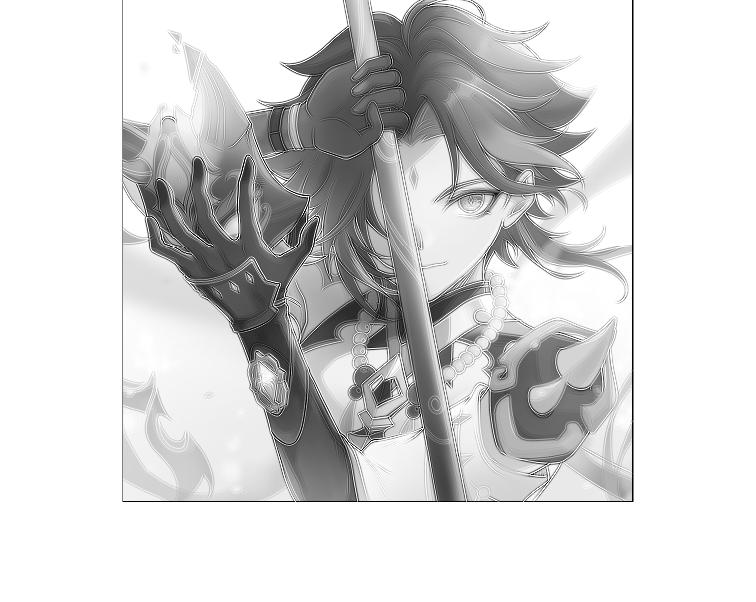

imwrite(ims + double(img) / 255, "exp5/sob_" + fn)
iml = filter2(fspecial("laplacian"),img) / 255;
imshow(iml + double(img) / 255)

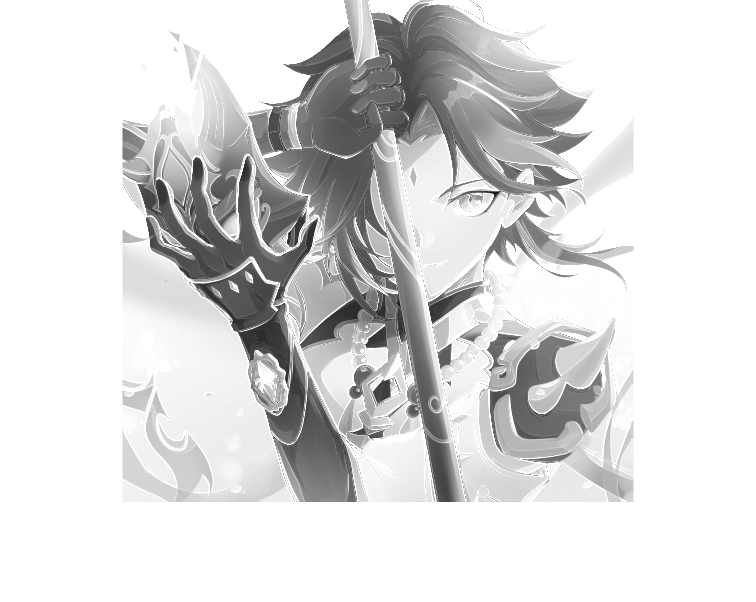

imwrite(iml + double(img) / 255, "exp5/lap_" + fn)
imr = imgradient(img, "roberts") / 255;
imshow(imr + double(img) / 255)

imwrite(imr + double(img) / 255, "exp5/rob_" + fn)

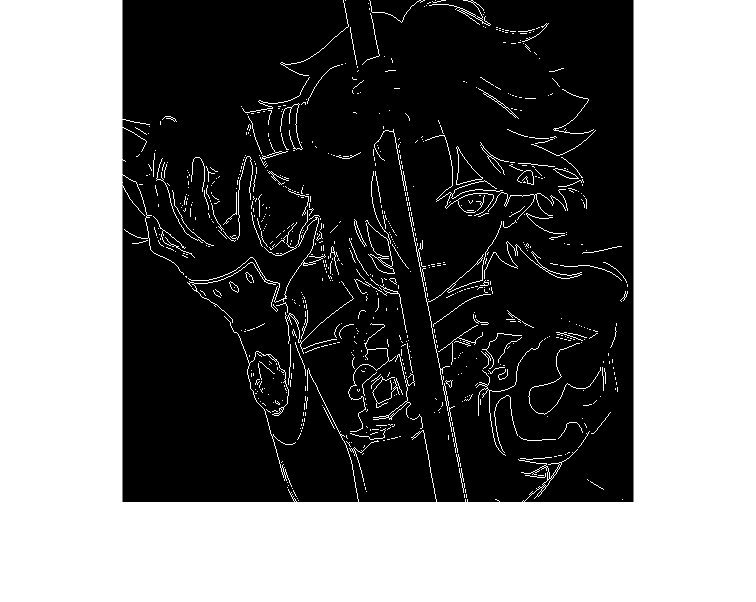

ims = edge(img,"sobel");
imshow(ims)

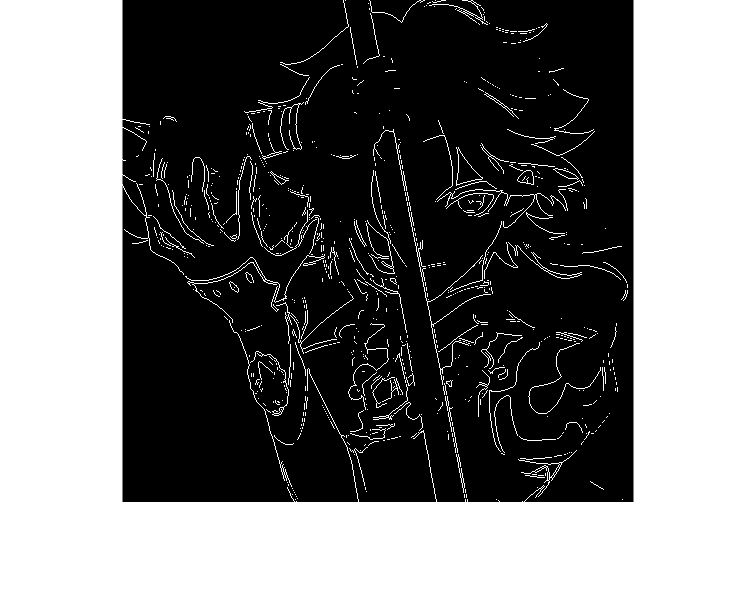

imwrite(ims, "exp5/sobel_" + fn)
imp = edge(img,"prewitt");
imshow(imp)

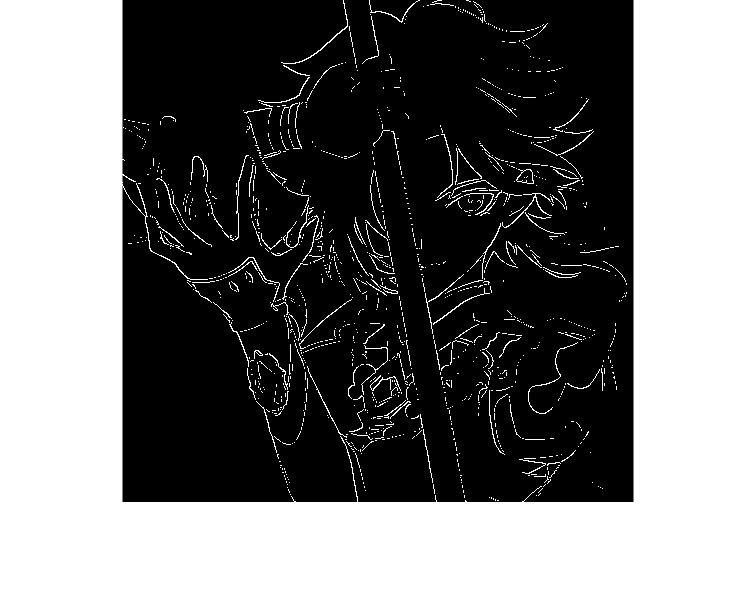

imwrite(imp, "exp5/prewitt_" + fn)
imr = edge(img,"roberts");
imshow(imr)

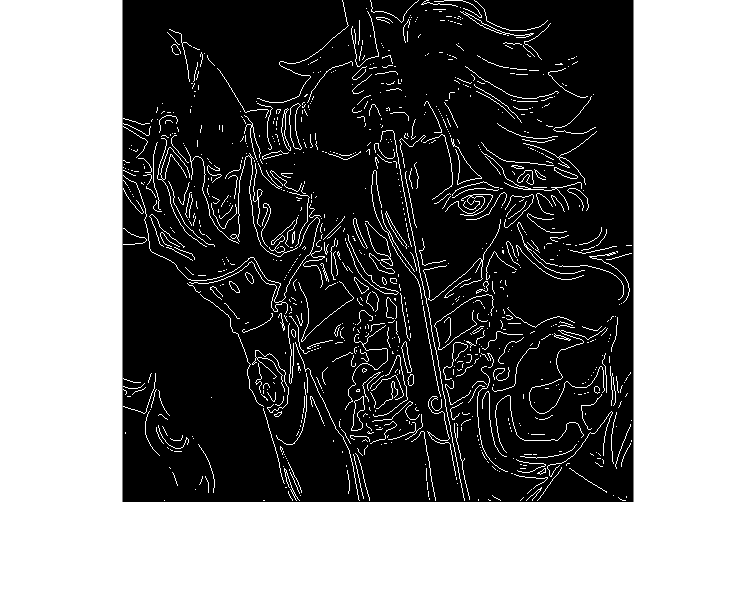

imwrite(imr, "exp5/roberts_" + fn)
iml = edge(img,"log");
imshow(iml)

imwrite(iml, "exp5/log_" + fn)
imz = edge(img,"zerocross");
imshow(imz)

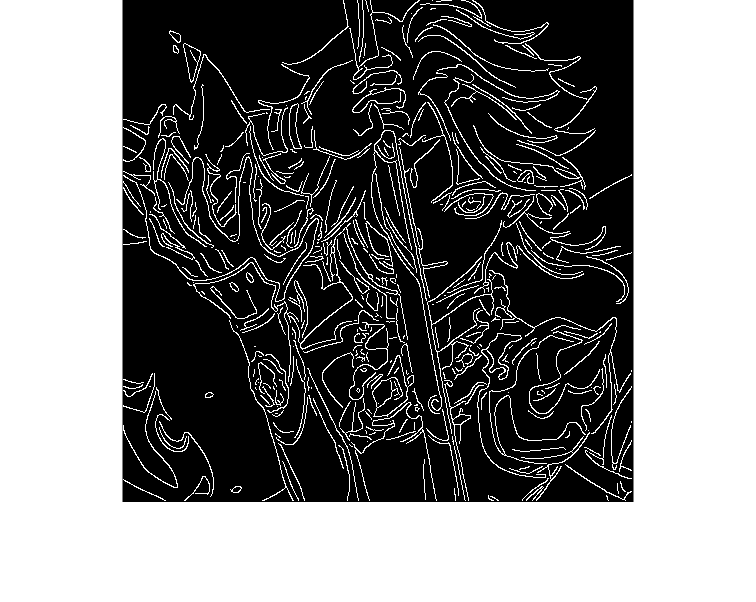

imwrite(imz, "exp5/zero_" + fn)
imc = edge(img,"canny");
imshow(imc)

imwrite(imc, "exp5/canny_" + fn)